### Offset Correction vs 1000 Samples

clear all; close all; clc;

torrespana = [40.42057,-3.664179,600];
ell = referenceEllipsoid('WGS84');

% 100.000 samples
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/samples/s6_mdphase_i20_c1_l1_n100000_mp.mat')
dphase_100000.lls = error_lls;
dphase_100000.nlls = error_nlls;
[dphase_100000.F_lls, dphase_100000.X_lls] = ecdf(error_lls);
[dphase_100000.F_nlls, dphase_100000.X_nlls] = ecdf(error_nlls);

% 200.000 samples
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/samples/s6_mdphase_i20_c1_l1_n200000_mp.mat')
dphase_200000.lls = error_lls;
dphase_200000.nlls = error_nlls;
[dphase_200000.F_lls, dphase_200000.X_lls] = ecdf(error_lls);
[dphase_200000.F_nlls, dphase_200000.X_nlls] = ecdf(error_nlls);

% 500.000 samples
load('/home/ygglc/desktop/phd/research/localization/core/localization-tdoa/matlab/sensys/madrid2/samples/s6_mdphase_i20_c1_l1_n500000_mp.mat')
dphase_500000.lls = error_lls;
dphase_500000.nlls = error_nlls;
[dphase_500000.F_lls, dphase_500000.X_lls] = ecdf(error_lls);
[dphase_500000.F_nlls, dphase_500000.X_nlls] = ecdf(error_nlls);

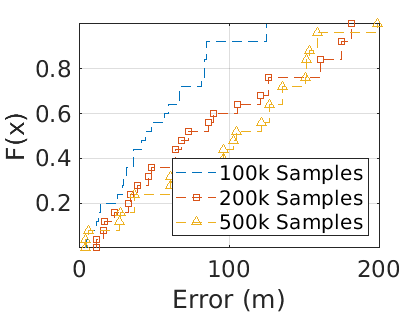

% Plotting
figure(); hold on; grid on; 
stairs(dphase_100000.X_nlls, dphase_100000.F_nlls, '--');
stairs(dphase_200000.X_nlls, dphase_200000.F_nlls, '--s');
stairs(dphase_500000.X_nlls, dphase_500000.F_nlls, '--^');
legend('100k', '200k', '500k','Location','southeast');
xlabel('Error (m)');
ylabel('F(x)');
yticks([0.2,0.4,0.6,0.8]);
box on;
xlim([0,200]);
set(gca,'FontSize',17);